# Interpolación de Polinomal de Newton

La interpolación polinomal responde a estimar a la función $f(x)$ como un polinómio de grado $n$ de la forma $f(x)=a_0+a_1x+a_2x^2+\cdots+a_nx^n$.

En el caso de la interpoación con polinómios de Newton se obtiene de la forma de representar el valor de una función en diferencias finitas. Por ejemplo, en el caso de la interpolación lineal $f_1(x)$ la interpolación esuna recta de la forma

$f_1(x)=f(x_0)+\frac{f(x_1)+f(x_0)}{x_1-x_0}(x_1-x_0)$,

de donde la pendiente es el término de la diferencia finita. Para el caso de la interpolación cuadrática $f_2(x)=b_0+b_1(x-x_0)+b_2(x-x_0)(x-x_1)$, los coeficientes de en términos de las defierencias finitas son:


$$b_1=\frac{f(x_1)-f(x_0)}{x_1-x_0}$$



$$b_2=\frac{\frac{f(x_2)-f(x_1)}{x_2-x_1}-\frac{f(x_1)-f(x_0)}{x_1-x_0}}{x_2-x_0}$$


donde la primera **diferencia finita **$f[x_i,x_j]=\frac{f(x_i)-f(x_j)}{x_i-x_j}$, la segunda diferencia finida $f[x_i,x_j,x_k]=\frac{f[x_i,x_j]-f[x_j,x_k]}{x_i-x_k}$

## 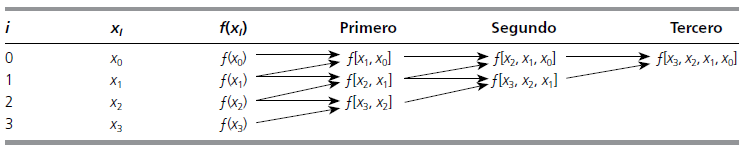

## Ejemplo: Estimar el valor de $ln(2)$ usando la interpolación de Newton

Recordando los términos de los coeficientes del polinómio de Newton hasta el grado 3:

Aproximamos el valor de $ln(2)$ usando iterpolación de Newton a partir de conocer los valores de $ln(1)$ y $ln(6)$.

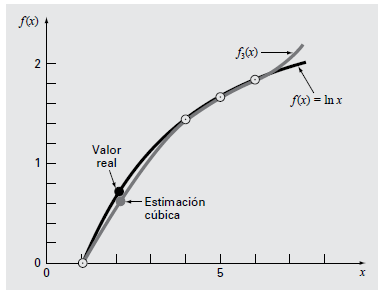

clc;
clear;

% Valores conocidos
x = [1, 6];
y = log(x);

% Diferencias divididas de Newton
n = length(x);
div_diff = zeros(n, n);
div_diff(:, 1) = y';

for j = 2:n
    for i = j:n
        div_diff(i, j) = (div_diff(i, j-1) - div_diff(i-1, j-1)) / (x(i) - x(i-j+1));
    end
end

% Coeficientes del polinomio de Newton
coeff = div_diff(n, :)

coeff =     1.7918    0.3584



% Evaluar el polinomio en x = 2
x_approx = 2;
P = coeff(n);
for k = n-1:-1:1
    P = P * (x_approx - x(k)) + coeff(k);
end

% Mostrar el resultado
fprintf('La aproximación de ln(2) usando interpolación de Newton es: %.15f\n', P);

La aproximación de ln(2) usando interpolación de Newton es: 2.150111363073666


Ahora usando los puntos $x=4$ y $x=6$ 

% Definir los puntos conocidos
x = [1,4,6];
y = log(x);

% Número de puntos
n = length(x);

% Inicializar la tabla de diferencias divididas
divided_diff_table = zeros(n, n);
divided_diff_table(:, 1) = y';

% Calcular las diferencias divididas
for j = 2:n
    for i = 1:(n-j+1)
        divided_diff_table(i, j) = (divided_diff_table(i+1, j-1) - divided_diff_table(i, j-1)) / (x(i+j-1) - x(i));
    end
end

% Coeficientes del polinomio de Newton
coefficients = divided_diff_table(1, :);

% Aproximar ln(2) usando el polinomio de interpolación de Newton
x_target = 2;
approx_ln2 = coefficients(1);
product_term = 1;

for i = 2:n
    product_term = product_term * (x_target - x(i-1));
    approx_ln2 = approx_ln2 + coefficients(i) * product_term;
end

% Mostrar el resultado
fprintf('Aproximación de ln(2) usando interpolación de Newton: %.15f\n', approx_ln2);

Aproximación de ln(2) usando interpolación de Newton: 0.565844346900983


# Interpolación con Polinomios de Lagrange

Los polinómios de interpolación de Lagrande son una reformulación de los polinómios de Newton donde $f(x)=\sum_{i=0}^{n}L_i(x)f(x_i)$ donde los coeficientes de Lagrande son de la forma $L_i(x)=\prod_{j=0,j \neq i}^{n}\frac{x-x_j}{x_i-x_j}$

% Definir los puntos de datos (x, y)
% Puedes ajustar estos puntos según sea necesario
x = [1, 4, 6];
y = log(x);

% Punto en el que se desea estimar ln(2)
x_est = 2;

% Inicializar el valor estimado
ln2_est = 0;

% Calcular el polinomio de Lagrange
n = length(x);
for i = 1:n
    % Calcular el término de Lagrange L_i(x)
    L_i = 1;
    for j = 1:n
        if j ~= i
            L_i = L_i * (x_est - x(j)) / (x(i) - x(j));
        end
    end
    % Sumar el término correspondiente al valor de y
    ln2_est = ln2_est + y(i) * L_i;
end

% Mostrar el resultado
fprintf('El valor estimado de ln(2) usando interpolación de Lagrange es: %.10f\n', ln2_est);

El valor estimado de ln(2) usando interpolación de Lagrange es: 0.5658443469


fprintf('El valor verdadero de ln(2) es: %.10f\n', log(2));

El valor verdadero de ln(2) es: 0.6931471806


fprintf('El error relativo es: %.10f%%\n', abs((ln2_est - log(2)) / log(2)) * 100);

El error relativo es: 18.3659166811%


Las interpolaciones con los dos métodos anteriores se pueden usar tanto con datos** igualmente espaciados** como con espaciado **no homogéneo**.

# Interpolación mediante trazadores (Splines)

Cuando se tienen $n+1$ puntos es posible ajustar un polinómio de grado $n$. Sin embargo, cuando la función no es un polinómio, es posible ajustar la función $f(x)$ por medio de tomar subconjuntos de $m$ datos y sobre ellos interpolar un polinómio de grado $m-1$. A estos polinómios se le conocen como *trazadores* o *splines.*

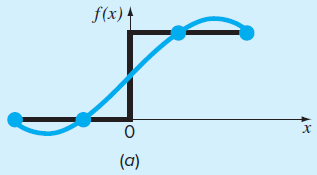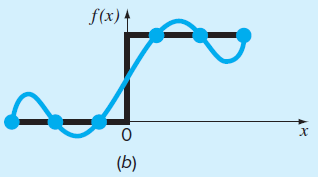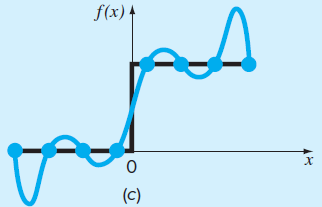

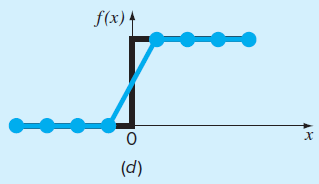

Por ejemplo, en las figuras se quiere interpolar la función escalón con polinómios de grado cada vez mas grande en el caso de las figuras *a - c*. Sin embargo, en la figura *d* se usa un polinómio de primer grado, lo que genera una mejor aproximación. Es decir, los trazadores se usan para aproximar mejor la función por sección, reproduciendo mejor el comportamiento cuando existen cambios abruptos de la función.

## Spline lineal

Si se tienen $n$ datos con $n-1$ intervalos, cada intervalo responde a un spline $s_i(x)$ que conecta a dons puntos de la forma $s_i(x)=a_i+b_i(x-x_i)$, donde $a_i=f_i$ y $b_i=\frac{f_{i+1}-f_i}{x_{i+1}-x_i}$. Donde cada función debe estar en el itervalo cerrado, es decir:


$$$\begin{array}{lcc}
f(x)=f(x_1)+m_1(x-x_1)&tal\; que&x_1\leq x\leq x_2\\
f(x)=f(x_2)+m_2(x-x_2)&tal\; que&x_2\leq x\leq x_3\\
\qquad\vdots&&\vdots\\
f(x)=f(x_{n-1})+m_{n-1}(x-x_{n-1})&tal\; que&x_{n-1}\leq x\leq x_n\\
\end{array}$$$


### Ejemplo

La interpolación por splines lineal de los datos:

% Datos de entrada
x = [3.0, 4.5, 7.0, 9.0]';
f = [2.5, 1.0, 2.5, 0.5]';

% Ordenar los datos
[x, sortIdx] = sort(x);
f = f(sortIdx);

% Calcular pendientes
n = length(x) - 1;
b = zeros(n, 1);
for i = 1:n
    b(i) = (f(i+1) - f(i)) / (x(i+1) - x(i));
end

% Crear tabla de resultados
results = table();
results.Punto = (1:length(x))';
results.x = x;
results.f_x_Exacto = f;
results.f_x_Interpolado = f; % Los puntos originales coinciden

% Añadir ecuaciones de interpolación
segmentos = cell(length(x),1);
segmentos{1} = 'Dato inicial';
for i = 1:n
    segmentos{i+1} = sprintf('f(x) = %.2f + %.2f(x-%.1f)', f(i), b(i), x(i));
end

results.Ecuacion_Segmento = segmentos;

% Mostrar tabla completa
disp(results);

    Punto     x     f_x_Exacto    f_x_Interpolado          Ecuacion_Segmento       
    _____    ___    __________    _______________    ______________________________

      1        3       2.5              2.5          {'Dato inicial'              }
      2      4.5         1                1          {'f(x) = 2.50 + -1.00(x-3.0)'}
      3        7       2.5              2.5          {'f(x) = 1.00 + 0.60(x-4.5)' }
      4        9       0.5              0.5          {'f(x) = 2.50 + -1.00(x-7.0)'}



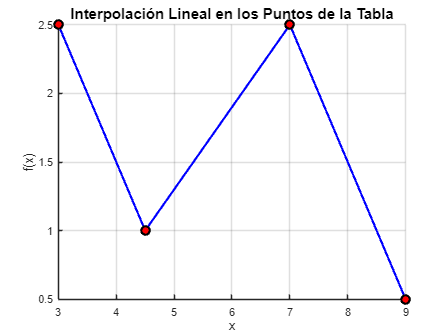

% 4. Gráfica
figure;
set(gcf, 'Color', 'w');
hold on;

% Dibujar los segmentos de recta
for i = 1:n
    plot([x(i) x(i+1)], [f(i) f(i+1)], 'b-o', ...
         'LineWidth', 2, 'MarkerSize', 8, ...
         'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'k');
end

grid on;
xlabel('x', 'FontSize', 12);
ylabel('f(x)', 'FontSize', 12);
title('Interpolación Lineal en los Puntos de la Tabla', 'FontSize', 14);

## Spline cuadratico

En una inerpolación de splines lineales, no es posible obtener la derivadas $m-esimas$ sobre cada uno de los puntos interpolados. Para obtener poder asegurar estas derivadas es necesario que el polinómio sea de grado al menos $m+1$. 

En el caso de los splines cuadraticos se interpola una función de la forma $f(x)=a_i+b_i(x-x_i)+c_i(x-x_i)^2$. Si son $n$ puntos entonces hay $n-1$ intervalos donde determinar la interpolación y por lo tanto habra $3(n-1)$ contantes $a's$, $b's$ y $c's$.

Para poder obtener los coeficientes de cada una de estas funciones se deben cumplir las siguientes condiciones debido a que la interpolación se realiza sobre cada dos datos:

- Los valores de la función de polinomios adyacentes deben ser iguales en los nodos interiores.  $f(x_i)=a_i+b_i(x_i-x_i)+c_i(x_i-x_i)^2$ esto implica que $f(x_i)=a_i$. Ya no es necesario determinar los coeficientes $a_i$ tan solo hay que determinar $c_i$ y $b_i$, por lo que haora solo habra que determinar $2(n-1)$ constantes.

- La primera y la última función deben pasar a través de los puntos extremos. Tendremos $2(n-1)-(n-1)=n-1$

- Las primeras derivadas en los nodos interiores deben ser iguales. Tendremos $(n-1)-(n-2)=1$

- Suponga que en el primer punto la segunda derivada es cero.

### Del Ejemplo

Tenemos cuatro puntos por lo que el númerto de intervalos es $n=3$. De la condición 1. y 2. y la 4.


$$\begin{array}{l}
f_1+b_1h_1=f_2\\
f_2+b_2h_3+c_2h_2^2=f_3\\
f_3+b_3h_3+c_3h_3^2=f_4\\
\end{array}$$


de donde podemos calcular 5 constantes $b_1$, $b_2$, $b_3$, $c_2$ y $c_3$. De la condicion 3.


$$\begin{array}{l}
b_1=b_2 \\
b_2+2c_2h_2=b_3
\end{array}$$


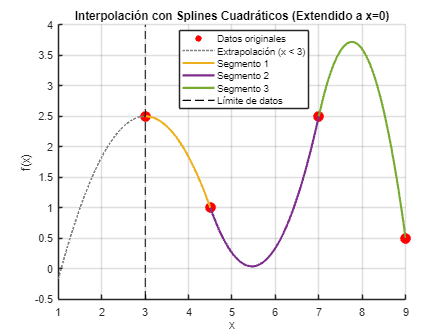

% Datos de entrada
x = [3.0, 4.5, 7.0, 9.0]';
y = [2.5, 1.0, 2.5, 0.5]';
n = length(x) - 1; % Número de intervalos

% 1. Construcción del sistema de ecuaciones
A = zeros(3*n, 3*n);
b = zeros(3*n, 1);

% Condición 1: Los splines pasan por los puntos (2n ecuaciones)
for i = 1:n
    % Punto izquierdo
    A(2*i-1, 3*i-2:3*i) = [x(i)^2, x(i), 1];
    b(2*i-1) = y(i);
    
    % Punto derecho
    A(2*i, 3*i-2:3*i) = [x(i+1)^2, x(i+1), 1];
    b(2*i) = y(i+1);
end

% Condición 2: Continuidad de la primera derivada en nodos internos
for i = 1:n-1
    row = 2*n + i;
    A(row, 3*i-2:3*i) = [2*x(i+1), 1, 0];
    A(row, 3*i+1:3*i+3) = [-2*x(i+1), -1, 0];
end

% Condición 3: Derivada cero en el primer punto (spline natural)
A(end, 1:3) = [2*x(1), 1, 0];

% 2. Resolver el sistema para los coeficientes
coeff = A\b;

% 3. Organizar coeficientes en matriz [a, b, c] para cada spline
splines = reshape(coeff, 3, n)';

% 4. Configuración de la gráfica
figure;
hold on;
grid on;
title('Interpolación con Splines Cuadráticos (Extendido a x=0)');
xlabel('x'); 
ylabel('f(x)');
scatter(x, y, 100, 'filled', 'r', 'DisplayName', 'Datos originales');

% 5. Graficar cada spline cuadrático con extensión a cero
x_min = 1; % Extendemos desde x = 0
x_max = max(x);

% Primer segmento extendido (desde x=0 hasta x=3)
x_segment_ext = linspace(x_min, x(1), 100);
y_segment_ext = splines(1,1)*x_segment_ext.^2 + splines(1,2)*x_segment_ext + splines(1,3);
plot(x_segment_ext, y_segment_ext, ':', 'LineWidth', 1.5, 'Color', [0.5 0.5 0.5], ...
    'DisplayName', 'Extrapolación (x < 3)');

% Segmentos originales
for i = 1:n
    x_segment = linspace(x(i), x(i+1), 100);
    y_segment = splines(i,1)*x_segment.^2 + splines(i,2)*x_segment + splines(i,3);
    plot(x_segment, y_segment, 'LineWidth', 2, 'DisplayName', sprintf('Segmento %d', i));
end

% Línea vertical en x=3 para marcar el inicio de los datos
line([3 3], ylim, 'Color', 'k', 'LineStyle', '--', 'LineWidth', 1, ...
    'DisplayName', 'Límite de datos');

legend("Position", [0.39934,0.67958,0.28929,0.22976])


% 6. Mostrar ecuaciones
fprintf('\nEcuaciones de los splines cuadráticos:\n');


Ecuaciones de los splines cuadráticos:


for i = 1:n
    fprintf('Segmento %d (%.1f ≤ x ≤ %.1f): ', i, x(i), x(i+1));
    fprintf('f(x) = %.4fx² + %.4fx + %.4f\n', splines(i,1), splines(i,2), splines(i,3));
end

Segmento 1 (3.0 ≤ x ≤ 4.5): 

f(x) = -0.6667x² + 4.0000x + -3.5000


Segmento 2 (4.5 ≤ x ≤ 7.0): 

f(x) = 1.0400x² + -11.3600x + 31.0600


Segmento 3 (7.0 ≤ x ≤ 9.0): 

f(x) = -2.1000x² + 32.6000x + -122.8000


## Spline cúbicos

Para el caso de esta interpolación se usa una función de la forma $f(x)=a_i+b_i(x-x_i)+c_i(x-x_i)^2+d_i(x-x_i)^3$

Las suposiciones que se utilizan para obtener los coeficientes siguen reglas similares. Hay que observar que la condición 4. fue impuesta de tal forma que facilitara los cálculos. Esta suposición se hace de la misma manera para los splines cúbicos de tal forma que despues del desarrollo de cada una de las condiciones (pp.403 Chapra en español) se obtiene una matriz de la forma:

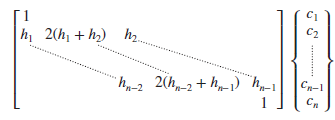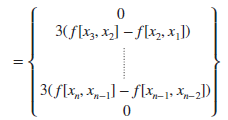

donde $f[x_{i+1},x_i]$ es la forma conocida de diferencias finitas. Al utilizar esta condición se le conoce como spline cpubico natural.

# Interpolación bilineal

Consideremos una función $z=f(x_i,y_i)$. En una interpolación bilineal se usa la ecuación de una superficie que cruce por cuatro puntos $f(x_j,y_j)$ para $j=1,2,3,4$, para estimar un punto intermedio entre estos $f(x_i,y_i)$ como se muestra en la primer figura.

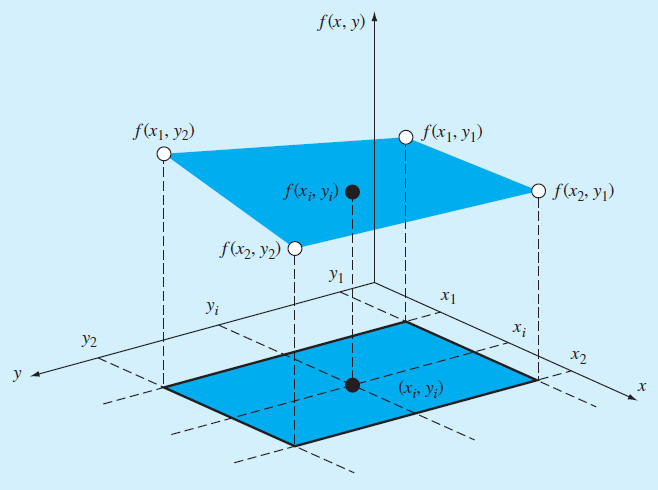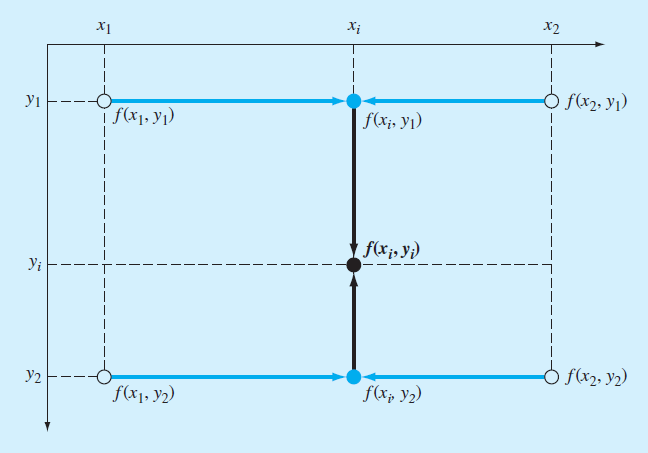

El método aproxima por medio de tres rectas el punto $f(x_i,y_i)$. Dos rectas fijas en los puntos $y_1$ y $y_2$ para todo $x_i\in(x_1,x_2)$. Estas rectas se pueden aproximar usando la interpolación de Lagrange como:

$f(x_i,y_1)=\frac{x_i-x_2}{x_1-x_2}f(x_1,y_1)+\frac{x_i-x_1}{x_2-x_1}f(x_2,y_1)$ para la recta fija en $y_1$ y,

$f(x_i,y_2)=\frac{x_i-x_2}{x_1-x_2}f(x_1,y_2)+\frac{x_i-x_1}{x_2-x_1}f(x_2,y_2)$ para la recta fija en $y_2$.

De tal forma que el punto buscado ahora se fija sobre el valor $x_i$ buscado y se resuelve el polinómio

$f(x_i,y_i)=\frac{y_i-y_2}{y_1-y_2}f(x_i,y_1)+\frac{y_i-y_1}{y_2-y_1}f(x_i,y_2)$.

## Ejemplo

 Supongamos cuatro mediciones de temperatura 

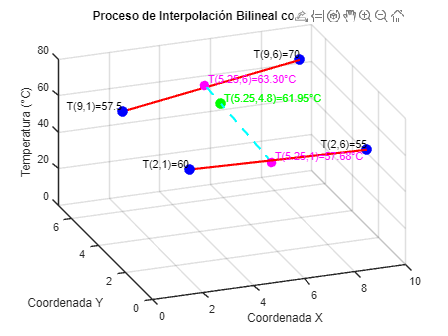

% Datos de entrada
x = [2, 9];          % Coordenadas x conocidas
y = [1, 6];          % Coordenadas y conocidas
[X, Y] = meshgrid(x, y);  % Crear malla de coordenadas
T = [60, 57.5; 55, 70];   % Temperaturas en los puntos (2,1), (9,1), (2,6), (9,6)

% Punto a interpolar
x_interp = 5.25;
y_interp = 4.8;

%% Interpolación bilineal usando polinomios de Lagrange
% Coeficientes de Lagrange para x
Lx1 = (x_interp - x(2))/(x(1) - x(2));  % L1 para x
Lx2 = (x_interp - x(1))/(x(2) - x(1));  % L2 para x

% Coeficientes de Lagrange para y
Ly1 = (y_interp - y(2))/(y(1) - y(2));  % L1 para y
Ly2 = (y_interp - y(1))/(y(2) - y(1));  % L2 para y

% Interpolación en x para y1=1 y y2=6
T_y1 = Lx1 * T(1,1) + Lx2 * T(2,1);  % T(5.25,1)
T_y2 = Lx1 * T(1,2) + Lx2 * T(2,2);  % T(5.25,6)

% Interpolación final en y
T_interp = Ly1 * T_y1 + Ly2 * T_y2;  % T(5.25,4.8)

%% Gráfica con líneas guía
figure;
hold on;
grid on;

% 1. Puntos originales
scatter3(X(:), Y(:), T(:), 100, 'filled', 'MarkerFaceColor', 'b');
text(X(:), Y(:), T(:), {'T(2,1)=60', 'T(9,1)=57.5', 'T(2,6)=55', 'T(9,6)=70'}, ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');

% 2. Línea entre T(2,1) y T(9,1) - para y=1
line([2 9], [1 1], [60 57.5], 'Color', 'r', 'LineWidth', 2);

% 3. Punto interpolado T(5.25,1)
scatter3(5.25, 1, T_y1, 80, 'filled', 'MarkerFaceColor', 'm');
text(5.25, 1, T_y1, sprintf(' T(5.25,1)=%.2f°C', T_y1), ...
    'Color', 'm', 'VerticalAlignment', 'bottom');

% 4. Línea entre T(2,6) y T(9,6) - para y=6
line([2 9], [6 6], [55 70], 'Color', 'r', 'LineWidth', 2);

% 5. Punto interpolado T(5.25,6)
scatter3(5.25, 6, T_y2, 80, 'filled', 'MarkerFaceColor', 'm');
text(5.25, 6, T_y2, sprintf(' T(5.25,6)=%.2f°C', T_y2), ...
    'Color', 'm', 'VerticalAlignment', 'bottom');

% 6. Línea entre T(5.25,1) y T(5.25,6)
line([5.25 5.25], [1 6], [T_y1 T_y2], 'Color', 'c', 'LineWidth', 2, 'LineStyle', '--');

% 7. Punto interpolado final T(5.25,4.8)
scatter3(x_interp, y_interp, T_interp, 100, 'g', 'filled', 'MarkerFaceColor', 'g');
text(x_interp, y_interp, T_interp, sprintf(' T(5.25,4.8)=%.2f°C', T_interp), ...
    'Color', 'g', 'VerticalAlignment', 'bottom');

% Configuración de la gráfica
xlabel('Coordenada X');
ylabel('Coordenada Y');
zlabel('Temperatura (°C)');
title('Proceso de Interpolación Bilineal con Líneas Guía');
view(3);  % Vista 3D
axis([0 10 0 7 0 80]);  % Ajuste de ejes
% legend('Datos conocidos', 'Líneas interpolación X', 'Puntos intermedios', ...
       % 'Línea interpolación Y', 'Punto final interpolado', 'Location', 'northeast');
hold off;

view([-20.3 34.5])


% Mostrar resultados en consola
fprintf('\nResultados de interpolación:\n');


Resultados de interpolación:


fprintf('T(5.25,1) = %.4f°C\n', T_y1);

T(5.25,1) = 57.6786°C


fprintf('T(5.25,6) = %.4f°C\n', T_y2);

T(5.25,6) = 63.3036°C


fprintf('T(5.25,4.8) = %.4f°C\n', T_interp);

T(5.25,4.8) = 61.9536°C


## Ejemplo

Vamos a suponer una prospección geofísica por pozos geotérmicos en cuatro diferentes localizaciones mas o menos cercanas. Todos los pozos tienen diferentes profundidades a un basamento sedimentario. En cada uno de los pozos se realizar mediciones cada 100 metros de la temperatura desde la superficie hasta el basamento sedimentaria, el pozo mas somero esta a 700 metros mientras que el mas profundo esta a 1800m. Todos las profundidades de cada uno de los pozos son diferentes entre si. Dos pozos contiguos son de granito cuyas  conductividad térmica varían con la profundidad debido a la cristalización mientras que los otros dos pozos son basaltos con conductividades térmicas que varían con la vesicularidad. 

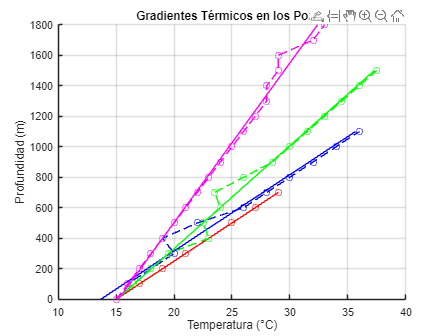

% Programa de análisis de datos geotérmicos en pozos

%% 1. Definición de los datos de los pozos

% Profundidades de los pozos (todos diferentes entre 700m y 1800m)
profundidades_pozos = [700, 1100, 1500, 1800]; % en metros

% Datos de temperatura para cada pozo (mediciones cada 100m)
% Asumimos datos sintéticos para este ejemplo
datos_temperatura = {
    % Pozo 1 (700m) - Granito
    [0 100 200 300 400 500 600 700; % Profundidad (m)
     15 17 19 21 23 25 27 29];     % Temperatura (°C)
    
    % Pozo 2 (1100m) - Basalto
    [0 100 200 300 400 500 600 700 800 900 1000 1100;
     15 16 18 20 19 22 26 28 30 32 34 36];
    
    % Pozo 3 (1500m) - Granito
    [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500;
     15 16.5 18 19.5 23 22.5 24 23.5 26 28.5 30 31.5 33 34.5 36 37.5];
    
    % Pozo 4 (1800m) - Basalto
    [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800;
     15 16 17 18 19 20 21 22 23 24 25 26 27 28 28 29 29 32 33]
};

% Tipo de roca para cada pozo (1=Granito, 2=Basalto)
tipo_roca = [1, 2, 1, 2];

%% 2. Cálculo del gradiente térmico para cada pozo

gradientes = zeros(1,4);
interceptos = zeros(1,4);

figure;
hold on;
colores = ['r', 'b', 'g', 'm'];
nombres = {'Pozo 1 (Granito)', 'Pozo 2 (Basalto)', 'Pozo 3 (Granito)', 'Pozo 4 (Basalto)'};

for i = 1:4
    profundidad = datos_temperatura{i}(1,:);
    temperatura = datos_temperatura{i}(2,:);
    
    % Ajuste lineal para el gradiente térmico
    p = polyfit(profundidad, temperatura, 1);
    gradientes(i) = p(1); % °C/m
    interceptos(i) = p(2); % Temperatura en superficie
    
    % Graficar datos y ajuste
    plot(temperatura, profundidad, [colores(i) '--o'], 'DisplayName', [nombres{i} ' - Datos']);
    plot(polyval(p, profundidad), profundidad, [colores(i) '-'], 'DisplayName', [nombres{i} ' - Ajuste']);
end

ylabel('Profundidad (m)');
xlabel('Temperatura (°C)');
title('Gradientes Térmicos en los Pozos');
% legend('Location', 'northwest');
grid on;
hold off;

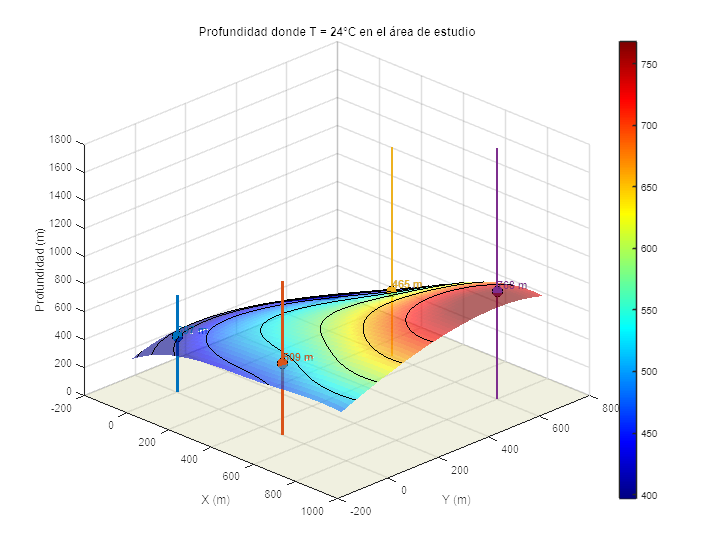




%% 4. Interpolación bilineal donde coinciden las temperaturas

% Encontrar la profundidad máxima común a todos los pozos
prof_max_comun = min(profundidades_pozos); % 700m en este caso

% Crear matriz de temperaturas en puntos comunes
prof_comunes = 0:100:prof_max_comun;
num_puntos = length(prof_comunes);
temp_comunes = zeros(num_puntos, 4);

for i = 1:4
    idx = ismember(datos_temperatura{i}(1,:), prof_comunes);
    temp_comunes(:,i) = datos_temperatura{i}(2,idx)';
end

% Coordenadas de los pozos (asumimos posiciones en un plano XY para la interpolación)
% Por simplicidad, colocamos los pozos en un cuadrado de 1000m de lado
x_pozos = [0, 1000, 0, 1000]; % Coordenadas X de los pozos
y_pozos = [0, 0, 1000, 1000]; % Coordenadas Y de los pozos


%% 1. Definición de la geometría de los pozos (trapecio irregular)

% Coordenadas X,Y de los pozos (formando un trapecio irregular)
x_pozos = [0, 500, 300, 800]; % Coordenadas X en metros
y_pozos = [0, 0, 600, 600];   % Coordenadas Y en metros
profundidades = [700, 1100, 1500, 1800]; % Profundidades de cada pozo en metros

% Nombres de los pozos
nombres_pozos = {'Pozo 1', 'Pozo 2', 'Pozo 3', 'Pozo 4'};

%% 2. Datos de temperatura sintéticos

% Crear perfiles de temperatura para cada pozo (gradiente variable)
temp_superficie = 15; % Temperatura en superficie común

% Pozo 1 (700m) - Granito
prof1 = 0:100:700;
temp1 = temp_superficie + (30-temp_superficie)*(prof1/700).^0.9;

% Pozo 2 (1100m) - Basalto
prof2 = 0:100:1100;
temp2 = temp_superficie + (36-temp_superficie)*(prof2/1100).^1.1;

% Pozo 3 (1500m) - Granito
prof3 = 0:100:1500;
temp3 = temp_superficie + (38-temp_superficie)*(prof3/1500).^0.8;

% Pozo 4 (1800m) - Basalto
prof4 = 0:100:1800;
temp4 = temp_superficie + (40-temp_superficie)*(prof4/1800).^1.2;

%% 3. Encontrar la profundidad donde cada pozo alcanza 24°C

prof_24C = zeros(1,4);

% Interpolación para encontrar profundidad a 24°C en cada pozo
prof_24C(1) = interp1(temp1, prof1, 24);
prof_24C(2) = interp1(temp2, prof2, 24);
prof_24C(3) = interp1(temp3, prof3, 24);
prof_24C(4) = interp1(temp4, prof4, 24);

%% 4. Interpolación de la profundidad a 24°C entre pozos

% Crear grid para interpolación
[x_grid, y_grid] = meshgrid(linspace(min(x_pozos)-100, max(x_pozos)+100, 50), ...
                     linspace(min(y_pozos)-100, max(y_pozos)+100, 50));

% Interpolación de la profundidad a 24°C usando griddata
prof_24C_interp = griddata(x_pozos, y_pozos, prof_24C, x_grid, y_grid, 'v4');

%% 5. Visualización 3D

figure('Position', [100, 100, 900, 700]);
hold on;
grid on;
view(45, 30);

% 1. Dibujar los pozos como líneas verticales
colors = lines(4);
for i = 1:4
    % Dibujar el pozo completo
    plot3([x_pozos(i) x_pozos(i)], [y_pozos(i) y_pozos(i)], [0 profundidades(i)], ...
          'Color', colors(i,:), 'LineWidth', 2.5, 'DisplayName', nombres_pozos{i});

    % Marcar el punto a 24°C
    plot3(x_pozos(i), y_pozos(i), prof_24C(i), 'o', 'MarkerSize', 10, ...
          'MarkerFaceColor', colors(i,:), 'MarkerEdgeColor', 'k');

    % Etiqueta con profundidad a 24°C
    text(x_pozos(i), y_pozos(i), prof_24C(i)+50, ...
         sprintf('%d m', round(prof_24C(i))), ...
         'Color', colors(i,:), 'FontWeight', 'bold');
end

% 2. Dibujar la superficie interpolada a 24°C
surf(x_grid, y_grid, prof_24C_interp, 'FaceAlpha', 0.6, 'EdgeColor', 'none');
colormap(jet);
colorbar;
caxis([min(prof_24C) max(prof_24C)]);
title('Profundidad donde T = 24°C');

% 3. Dibujar el plano del terreno (z=0)
[x_terreno, y_terreno] = meshgrid(linspace(min(x_pozos)-200, max(x_pozos)+200, 10), ...
                          linspace(min(y_pozos)-200, max(y_pozos)+200, 10));
surf(x_terreno, y_terreno, zeros(size(x_terreno)), ...
     'FaceColor', [0.8 0.8 0.6], 'FaceAlpha', 0.3, 'EdgeColor', 'none');

% 4. Configuración de la gráfica
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Profundidad (m)');
title('Profundidad donde T = 24°C en el área de estudio');
% legend('Location', 'northeast');

% 5. Añadir contornos en el plano XY
contour3(x_grid, y_grid, prof_24C_interp, 10, 'k-', 'LineWidth', 0.5);

hold off;
rotate3d on;


%% 6. Mostrar resultados numéricos
nombres_pozos = {'Pozo 1 (Granito)'; 'Pozo 2 (Basalto)'; 'Pozo 3 (Granito)'; 'Pozo 4 (Basalto)'};
tabla_24C = table(nombres_pozos, prof_24C',  ...
    'VariableNames', {'Pozo', 'Profundidad a 24°C'});
disp('Tabla de Gradientes Térmicos y Flujos de Calor:');

Tabla de Gradientes Térmicos y Flujos de Calor:


disp(tabla_24C)

            Pozo            Profundidad a 24°C
    ____________________    __________________

    {'Pozo 1 (Granito)'}          396.87      
    {'Pozo 2 (Basalto)'}           509.1      
    {'Pozo 3 (Granito)'}          464.74      
    {'Pozo 4 (Basalto)'}             768      



La función de interpoloación *interp1* tiene varias opciones de métodos para interpolar, entre los mas comunes estan: